# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## This tutorial

Create fake data for a hypothetical extracellular electrophysiology experiment. The types of data we will convert are:

- Voltage recording

- Local field potential (LFP)

- Spike times

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a session_description, identifier, and session start time. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object with those and additional metadata. For all MatNWB functions, we use the Matlab method of entering keyword argument pairs, where arguments are entered as name followed by value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

nwb =   NwbFile with properties:

                                             nwb_version: '2.7.0'
                                        file_create_date: []
                                              identifier: 'Mouse5_Day3'
                                     session_description: 'mouse in open exploration'
                                      session_start_time: {[2018-04-25T02:30:03.000000+02:00]}
                               timestamps_reference_time: {[2018-04-25T03:00:45.000000+02:00]}
                                             acquisition: [0×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: ''
                                         general_devices: [0×1 types.untyped.Set]
                          general_expe

## Extracellular Electrophysiology

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: `x`, `y`, `z`, `impedance`, `location`, `filtering`, and `electrode_group`.

## Electrodes Table

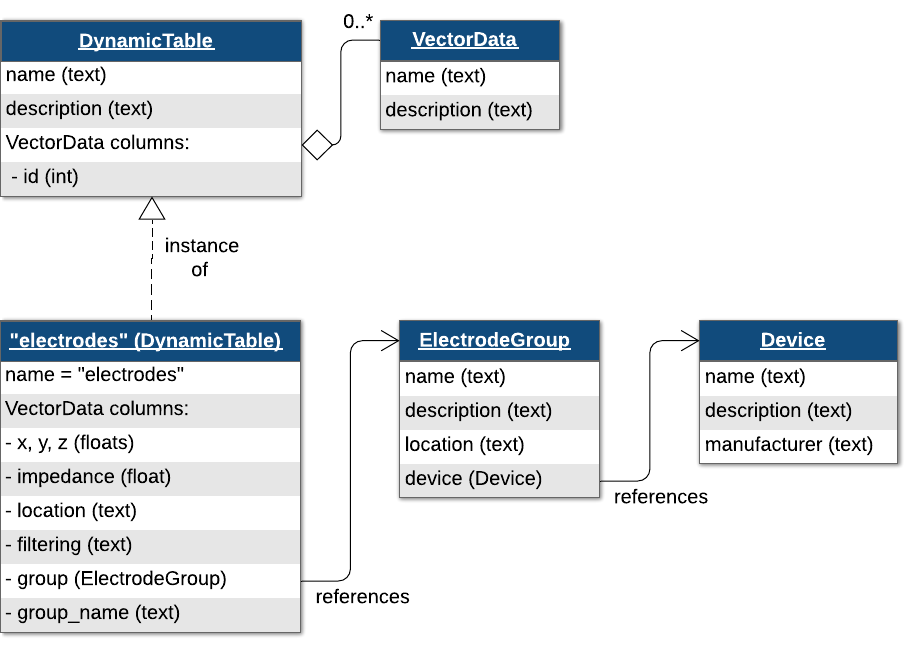

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

numShanks = 4;
numChannelsPerShank = 3;

ElectrodesDynamicTable = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

Device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', Device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    EGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(Device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, EGroup);
    for iElectrode = 1:numChannelsPerShank
        ElectrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(EGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
ElectrodesDynamicTable.toTable() % Display the table

ans = 12×5 table
    id     location                 group                group_name            label        
    __    ___________    ____________________________    __________    _____________________

     0    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode1'}
     1    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode2'}
     2    {'unknown'}    1×1 types.untyped.ObjectView    {'shank1'}    {'shank1-electrode3'}
     3    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode1'}
     4    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode2'}
     5    {'unknown'}    1×1 types.untyped.ObjectView    {'shank2'}    {'shank2-electrode3'}
     6    {'unknown'}    1×1 types.untyped.ObjectView    {'shank3'} 


nwb.general_extracellular_ephys_electrodes = ElectrodesDynamicTable;

## Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is an object that allow you to create a link from one neurodata type referencing another. 

## ElectricalSeries

Voltage data are stored in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) is a subclass of [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) specialized for voltage data. In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we will need to reference a set of rows in the `electrodes` table to indicate which electrodes were recorded. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, by row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(ElectrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(ElectrodesDynamicTable.id.data)-1)');

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

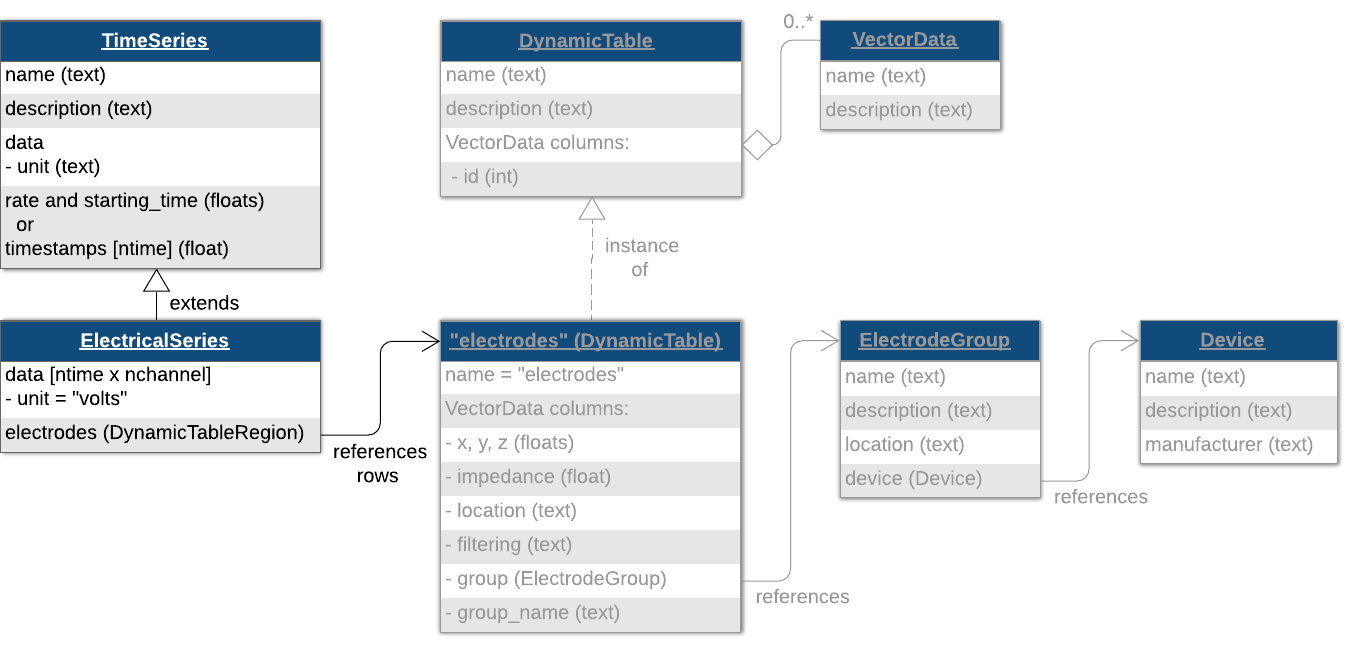

electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(12, 3000), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group. 

nwb.acquisition.set('ElectricalSeries', electrical_series);

## LFP

Local field potential (LFP) refers in this case to data that has been downsampled and/or filtered from the original acquisition data and is used to analyze signals in the lower frequency range. Filtered and downsampled LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, store it inside an `LFP` object, then place the `LFP` object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` earlier.

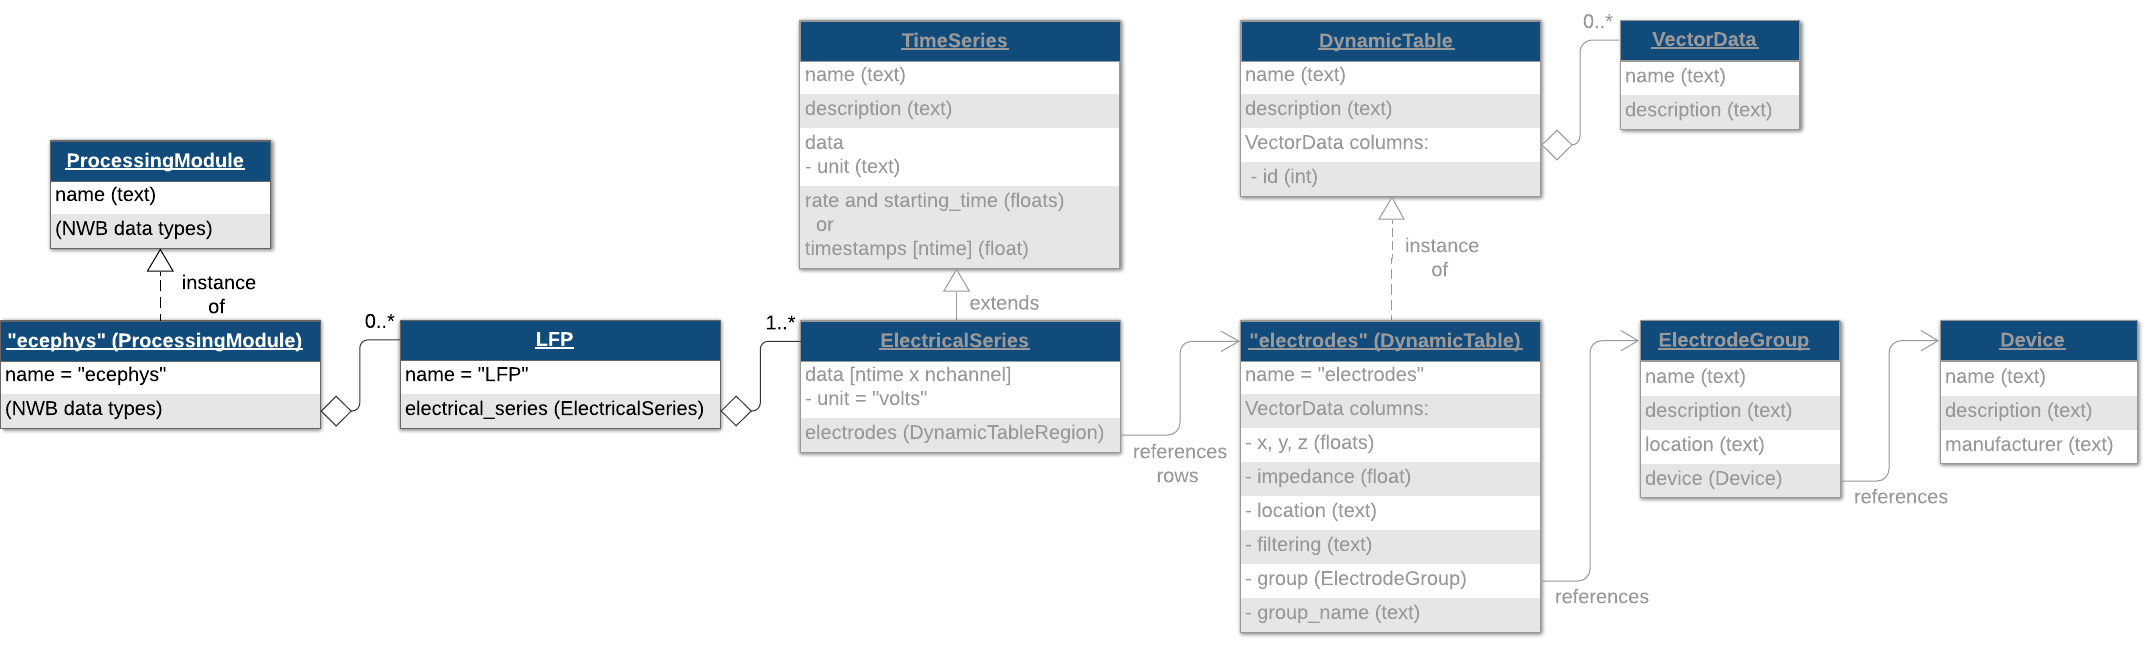

lfp_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(12, 100), ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', lfp_electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

### Decomposition of LFP Data into Frequency Bands

In some cases, you may want to further process the LFP data and decompose the signal into different frequency bands for additional downstream analyses. You can store the processed data from these spectral analyses using a [`DecompositionSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/DecompositionSeries.html) object. This object allows you to include metadata about the frequency bands and metric used (e.g., `power`, `phase`, `amplitude`), as well as link the decomposed data to the original [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) signal the data was derived from.

**Note**: When adding data to a [`DecompositionSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/DecompositionSeries.html), the `data` argument is assumed to be 3D where the first dimension is time, the second dimension is channels, and the third dimension is bands. In MatNWB, the data needs to be permuted because the dimensions are written to file in reverse order (See the [dimensionMapNoDataPipes](matlab:open('./dimensionMapNoDataPipes.mlx')) tutorial)

% Define the frequency bands of interest (in Hz):
band_names = {'theta'; 'beta'; 'gamma'};
band_mean = [8; 21; 55];
band_stdev = [2; 4.5; 12.5];
band_limits = [band_mean - 2*band_stdev, band_mean + 2*band_stdev];

% The bands should be added to the DecompositionSeries as a dynamic table
bands = table(band_names, band_mean, band_stdev, band_limits, ...
    'VariableNames', {'band_names', 'band_mean', 'band_stdev', 'band_limits'})

bands = 3×4 table
    band_names    band_mean    band_stdev    band_limits
    __________    _________    __________    ___________

    {'theta'}         8              2         4    12  
    {'beta' }        21            4.5        12    30  
    {'gamma'}        55           12.5        30    80  



bands = util.table2nwb( bands );

% Generate random phase data for the demonstration.
phase_data = randn(50, 12, numel(band_names)); % 50 samples, 12 channels, 3 frequency bands
phase_data = permute(phase_data, [3,2,1]); % See dimensionMapNoDataPipes tutorial

decomp_series = types.core.DecompositionSeries(...
    'data', phase_data, ...
    'bands', bands, ...
    'metric', 'phase', ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000.0, ... % Hz
    'source_channels', electrode_table_region, ...
    'source_timeseries', lfp_electrical_series);

% Add decomposition series to ecephys module
ecephys_module.nwbdatainterface.set('theta', decomp_series);

## Sorted Spike Times

#### Ragged Arrays

Spike times are stored in another [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) of subtype [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html). The default `Units` table is at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials`. Here, we generate some random spike data and populate the table. 

num_cells = 10;
firing_rate = 20;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

spikes = 1×10 cell array
    {[0.1848 0.8432 0.2635 0.0723 0.2240 0.5687 0.1469 0.9255 0.5765 0.5020 0.5943 0.7363 0.0999 0.4758 0.0660 0.1907 0.7332 0.7317 0.1012 0.0485 0.8992 0.3216 0.7111 0.9048 7.1465e-04 0.8913 0.7602 0.4694]}    {[0.8005 0.3923 0.1182 0.3748 0.2431 0.0308 0.5381 0.4824 0.0410 0.8633 0.1190 0.8563 0.8318 0.9418 0.8034 0.4114 0.9830 0.0345]}    {[0.0831 0.5715 0.0362 0.3140 0.6922 0.2182 0.5970 0.5196 0.5024 0.0182 0.0758 0.6116 0.6676 0.8014 0.0609 0.3691]}    {[0.4408 0.3560 0.4622 0.6822 0.5209 0.0519 0.0422 0.7255 0.3686 0.0760 0.1969 0.1221 0.0935 0.2710 0.5142 0.3935 0.6817 0.7547 0.5539]}    {[0.7548 0.8081 0.5018 0.4256 0.5550 0.5393 0.6676 0.2002 0.6200 0.2652 0.9656 0.9764 0.8088 0.6265 0.9117 0.4561 0.6521 0.0419 0.1285 0.1537]}    {[0.7977 0.8086 0.3701 0.1773 0.4944 0.1097 0.0846 0.2043 0.5298 0.8338 0.8993 0.9436 0.1810 0.8188 0.6257 0.7568 0.1103 0.8643 0.1217 0.5133 0.5856 0.9612 0.6723 0.0436 0.2547]}    {[0.0068 0.2100 0.0642 0.7569 0.9908 0.9157

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the units [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). These indexed columns have two components, the vector data object that holds the data and the vector index object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects.

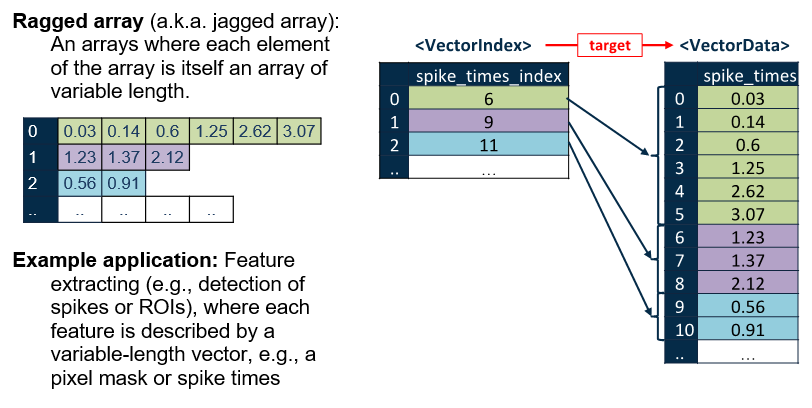

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

nwb.units.toTable

ans = 10×2 table
    id     spike_times 
    __    _____________

     1    {28×1 double}
     2    {18×1 double}
     3    {16×1 double}
     4    {19×1 double}
     5    {20×1 double}
     6    {25×1 double}
     7    {19×1 double}
     8    {22×1 double}
     9    {23×1 double}
    10    {19×1 double}


## Unsorted Spike Times

In MATLAB, while the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is used to store spike times and waveform data for spike-sorted, single-unit activity, you may also want to store spike times and waveform snippets of unsorted spiking activity. This is useful for recording multi-unit activity detected via threshold crossings during data acquisition. Such information can be stored using [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

% In the SpikeEventSeries the dimensions should be ordered as 
% [num_events, num_channels, num_samples].
% Define spike snippets: 20 events, 3 channels, 40 samples per event. 
spike_snippets = rand(20, 3, 40);
% Permute spike snippets (See dimensionMapNoDataPipes tutorial)
spike_snippets = permute(spike_snippets, [3,2,1]) 

spike_snippets = spike_snippets(:,:,1) =

    0.1624    0.3893    0.6306
    0.6864    0.8863    0.0681
    0.4833    0.4627    0.3871
    0.7410    0.1173    0.8211
    0.5852    0.2244    0.1087
    0.8740    0.8694    0.3867
    0.5130    0.4076    0.6495
    0.0909    0.8626    0.8491
    0.1469    0.1669    0.9649
    0.4419    0.2745    0.1281
    0.5607    0.7444    0.3493
    0.2603    0.7704    0.7977
    0.0277    0.9942    0.8309
    0.1132    0.1738    0.1022
    0.1152    0.1138    0.9419
    0.6720    0.0115    0.0434
    0.1016    0.1595    0.6937
    0.4163    0.0946    0.4944
    0.2359    0.4640    0.5428
    0.7867    0.2213    0.0055
    0.9977    0.9575    0.7167
    0.4345    0.4725    0.8634
    0.5396    0.6593    0.1869
    0.2944    0.2045    0.3622
    0.9334    0.5108    0.2607
    0.6815    0.7681    0.6543
    0.8004    0.1753    0.4928
    0.4602    0.5997    0.0167
    0.4643    0.2177    0.6134
    0.5681    0.0705    0.1280
    0.1740    0.8748    0.45


% Create electrode table region referencing electrodes 0, 1, and 2
shank0_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(ElectrodesDynamicTable), ...
    'description', 'shank0', ...
    'data', (0:2)');

% Define spike event series for unsorted spike times
spike_events = types.core.SpikeEventSeries( ...
    'data', spike_snippets, ...
    'timestamps', (0:19)', ...  % Timestamps for each event
    'description', 'events detected with 100uV threshold', ...
    'electrodes', shank0_table_region ...
);

% Add spike event series to NWB file acquisition
nwb.acquisition.set('SpikeEvents_Shank0', spike_events);

## Designating Electrophysiology Data

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing specific types of extracellular recordings. In addition to this [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class, NWB provides some [Processing Modules](https://pynwb.readthedocs.io/en/stable/tutorials/general/plot_file.html#modules-overview) for designating the type of data you are storing. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and [**Intro to NWB**](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html) for more details on using these objects.

For storing unsorted spiking data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the raw voltage traces and only the waveform ‘snippets’ surrounding spike events, you should use [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. The [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table can hold just the spike times of sorted units or, optionally, include additional waveform information. You can use the optional predefined columns `waveform_mean`, `waveform_sd`, and `waveforms` in the  [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table to store individual and mean waveform data.

For local field potential data, there are two options. Again, which one you choose depends on what data you have available. With both options, you should store your traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects. If you are storing unfiltered local field potential data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) data interface object(s). If you have filtered LFP data, you should store the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in [`FilteredEphys`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FilteredEphys.html) data interface object(s).

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

ans =    -0.0189    0.6169    1.4631    1.5405   -0.7244    0.1833   -1.1145   -0.0729   -0.0408    0.6805
    0.7192    0.7552   -0.1703   -0.6720   -0.3221   -0.4088    0.0606   -0.8893    1.2469   -0.4374
    0.3253   -0.3711   -0.9743   -0.6373   -1.0956    1.2375    0.0234    0.2446   -1.4538    2.7296
    0.6196    1.5832   -0.1684   -0.4226   -0.6467   -0.4222   -1.2761    0.6612    0.7488   -1.8353
    0.6517   -0.2256    0.7313    0.1046   -0.8900   -0.0548    0.6998    1.1780   -0.4497    0.7894



% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

ans =     0.1848
    0.8432
    0.2635
    0.0723
    0.2240
    0.5687
    0.1469
    0.9255
    0.5765
    0.5020


# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)